## MT3005 - Clase 9

De nuevo estaremos considerando el ejemplo del manipulador serial RR

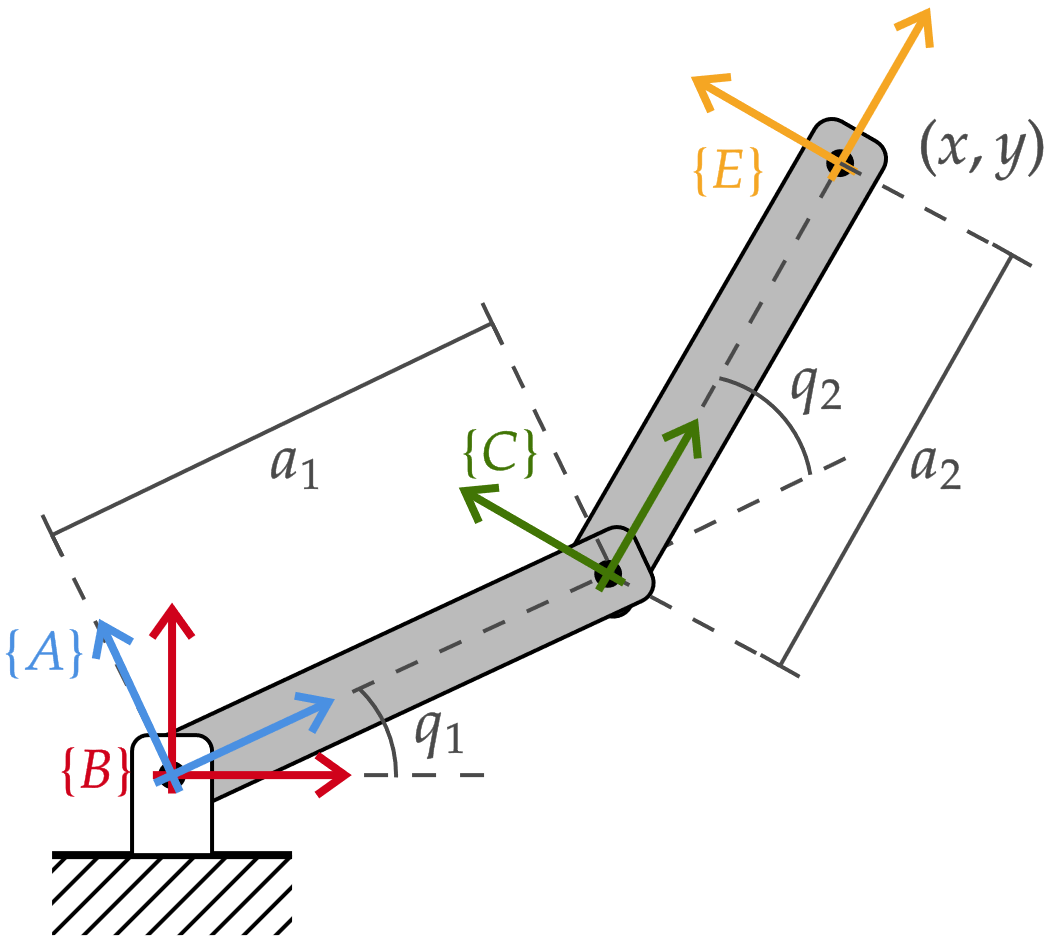

para el cual calcularemos la cinemática inversa mediante dos métodos distintos: usando el solver de MATLAB y mediante la Robotics Toolbox de Peter Corke. Tomemos en consideración que el espacio de tarea para este caso está dado por la posición del efector final [x;y].

Primero, empleemos matemática simbólica para resolver algebráicamente el problema

% Parámetros del robot
a1 = 1;
a2 = 1;
syms q1 q2

% Definimos la pose del efector final del manipulador
BT_E = simplify(trot2(q1)*transl2(a1,0)*trot2(q2)*transl2(a2,0));

% Extraemos la cinemática directa (posición del efector final)
K(q1, q2) = BT_E(1:2,3);

% Definimos variables simbólicas para la posición del efector final
syms x y

% Empleamos el solver para resolver el problema de cinemática inversa
[s1, s2] = solve([x;y] == K(q1,q2), [q1, q2])

$$s1 = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{2\,y+\sigma_{2}+\sigma_{1}}{x^{2}+2\,x+y^{2}}\right)\\ -2\,\mathrm{atan}\left(\frac{\sigma_{2}-2\,y+\sigma_{1}}{x^{2}+2\,x+y^{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{y^{2}\,\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\\ \sigma_{2}=\frac{x^{2}\,\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}} \end{array}$$

$$s2 = \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right)\\ 2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right) \end{array}\right)$$


% Definimos la cinemática inversa como (estas son las soluciones positivas)
ikq1(x,y) = 2*atan((2*y - (- x^4 - 2*x^2*y^2 + 4*x^2 - y^4 + 4*y^2)^(1/2))/(x^2 + 2*x + y^2));
ikq2(x,y) = 2*atan((-(x^2 + y^2)*(x^2 + y^2 - 4))^(1/2)/(x^2 + y^2));

% Definimos una pose del efector final de prueba
tsk = double(subs(BT_E, {q1, q2}, {0.5, 0.5}));
tsk_t = tsk(1:2,3)

tsk_t =     1.4179
    1.3209



% Calculamos la cinemática inversa para la pose deseada
double(ikq1(tsk_t(1), tsk_t(2)))

ans = 0.5000

double(ikq2(tsk_t(1), tsk_t(2)))

ans = 0.5000

Por otro lado, podemos de nuevo definir el robot como un objeto SerialLink para emplear la Robotics Toolbox:

% Definimos al manipulador planar RR
J1 = Revolute('a', a1);
J2 = Revolute('a', a2);
planRR = SerialLink([J1, J2], 'name', 'planRR')

 
planRR = 
 
planRR:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



% Definimos una pose del efector final de prueba
tsk = planRR.fkine([0.5, 0.5]);

% Calculamos la cinemática inversa para la pose deseada
cfg = planRR.ikine(tsk, 'mask', [1,1,0,0,0,0], 'q0', [0, 0])

cfg =     0.5000    0.5000



% Verificamos que esta configuración regresa la pose deseada
planRR.fkine(cfg)

 

ans = 
    0.5403   -0.8415         0     1.418
    0.8415    0.5403         0     1.321
         0         0         1         0
         0         0         0         1


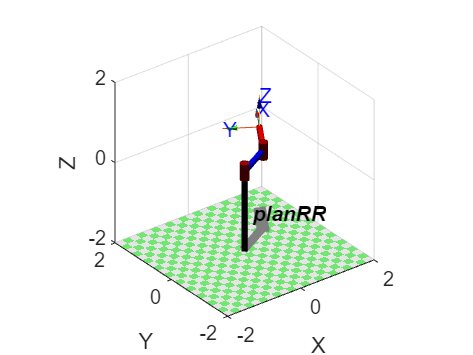

planRR.plot(cfg)